Load csv spreadsheet with all the knapsack data and show contents

Xall = readtable('Xall_figures.csv')

Xall = 2555×36 table
    Var1    participant_id    session_num    instance_num    attempt_num    treatment_cat    sahni_k      alpha       v_w_corr_pearson    mzn_props    attempt_submitted    time_on_task    length_of_sequence    num_unique_sets_in_seq    attempt_value    attempt_weight    solution_value    capacity    attempt_value_pct_solution    attempt_correct    len_sp_to_sol    ln_sp_first_tn_to_sol    ln_sp_last_tn_to_sol    num_items_overlap_first_tn_sol_set    num_items_overlap_last_tn_sol_set    alpha_attempt_set    mzn_props_attempt

Load cantab SWMSX (Spatial Working Memory) data and merge with knapsack data 

Yall=readtable('PECO_CANTAB_data_PB_SWMSX.csv');

ZallSWMSX=outerjoin(Xall,Yall,'LeftKeys',[2 3],'RightKeys',[2,3]);
writetable(ZallSWMSX,'ZallSWMSX.csv')

MANUALLY REORDER so participant 3 is first in ZallSWMSX!! Then reload. This way PLC is baseline (participants 3 started with PLC; If you do not reorder, then the assignment of columns of B() below to treatments has to be altered!)

% REORDER so participant 3 is first
Zall=readtable('ZallSWMSX.csv');

Correlate average Cantab score with DIFFERENCE in individual deviations from average treatment effect (random effects) between treatment = MOD and treatment = PLC (used to generate Fig S9).


% 1. First compute scores on Cantab per participants (categorical)
% Pick all rows - unless drug effect is needed, in which case, use:
% Pick treatment: MOD=treat 2, DEX=treat 1, MPH=treat 3, PLC=treat 0
% choose_treat = 0;
% rows=Zall.treatment==choose_treat;
rows = (Zall.Drug_Xall==1)|(Zall.Drug_Xall==0); 
xbar = grpstats(Zall.SWMSX(rows),Zall.participant(rows),{'mean'});

% 2. Second generate effects of treatments on performance (or any other regressand)
modelspec = 'attempt_correct ~ sahni_k + Complexity + treatment_cat + (1 + treatment_cat|participant_id)';
mdl = fitglme(Zall,modelspec,'Distribution','binomial','Link','logit')

mdl = Generalized linear mixed-effects model fit by PL

Model information:
    Number of observations            2555
    Fixed effects coefficients           6
    Random effects coefficients        160
    Covariance parameters               10
    Distribution                    Binomial
    Link                            Logit 
    FitMethod                       MPL   

Formula:
    attempt_correct ~ 1 + treatment_cat + sahni_k + Complexity + (1 + treatment_cat | participant_id)

Model fit statistics:
    AIC      BIC      LogLikelihood    Deviance
    11435    11528    -5701.4          11403   

Fixed effects coefficients (95% CIs):
    Name                         Estimate      SE           tStat       DF      pValue        Lower        Upper     
    {'(Intercept)'      }            1.6071      0.22628      7.1021    2549    1.5867e-12       1.1634        2.0508
    {'treatment_cat_DEX'}      


% 3. Next pick individual random effects of chosen treatment (individual
% deviations from mean treatment effect)
% Compute DIFFERENCES in individual random effects treatment vs. PLC
% If data were rearranged so participants 3 is first so that PLC is baseline 
% (see first line in this section) 
% then, in matrix B, columns relate to treatments as follows:
% 1=PLC,2=DEX,3=MPH,4=MOD
% [psi,mse,stats]=covarianceParameters(mdl);
choose_treat = 4;
[B,BNames,statsB]=randomEffects(mdl);
IndDev = B(choose_treat:4:end) - B(1:4:end);

% 4. Finally plot relation individual treatment effects for knapsack task and
% score on CANTAB and compute regression slope confidence intervals
plot(xbar,IndDev,'ob')
[BB BBint] = regress(IndDev,[ones(size(xbar)) xbar],0.1587)

BB =    -0.1500
    0.0158


BBint =    -0.6894    0.3894
   -0.0364    0.0680


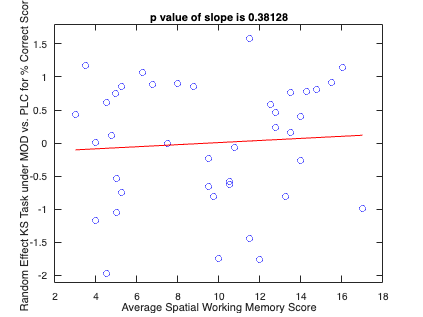

hold on;
plot(xbar,xbar.*BB(2)+BB(1),'-r');
axis([2 18 -2.1 1.8]);
xlabel('Average Spatial Working Memory Score')
ylabel('Random Effect KS Task under MOD vs. PLC for % Correct Score')
se = BBint(2,2) - BB(2);
pval = 1-normcdf(BB(2)./se);
tkst = ['p value of slope is ', num2str(pval)];
title(tkst)
hold off;

Load cantab Simple Reaction Time Task data and merge with knapsack data 

Yall=readtable('PECO_CANTAB_reactiontime.csv');

ZallRT=outerjoin(Xall,Yall,'LeftKeys',[2 3],'RightKeys',[2,3]);
writetable(ZallRT,'ZallRT.csv')

MANUALLY REORDER so participant 3 is first in ZallRT!! Then reload. This way PLC is baseline (participants 3 started with PLC; If you do not reorder, then the assignment of columns of B() below to treatments has to be altered!)

% REORDER so participant 3 is first
Zall=readtable('ZallRT.csv');

Correlate average Cantab score with DIFFERENCE in individual deviations from average treatment effect (random effects) between treatment = MOD and treatment = PLC (used to generate Fig S9).


% 1. First compute scores on Cantab per participants (categorical)
% Pick all rows - unless drug effect is needed, in which case, use:
% Pick treatment: MOD=treat 2, DEX=treat 1, MPH=treat 3, PLC=treat 0
% choose_treat = 0;
% rows=Zall.treatment==choose_treat;
rows = (Zall.Drug_Xall==1)|(Zall.Drug_Xall==0); 
xbar = grpstats(Zall.RTISMRT(rows),Zall.participant(rows),{'mean'});

% 2. Second generate effects of treatments on performance (or any other regressand)
modelspec = 'attempt_correct ~ sahni_k + Complexity + treatment_cat + (1 + treatment_cat|participant_id)';
mdl = fitglme(Zall,modelspec,'Distribution','binomial','Link','logit')

mdl = Generalized linear mixed-effects model fit by PL

Model information:
    Number of observations            2555
    Fixed effects coefficients           6
    Random effects coefficients        160
    Covariance parameters               10
    Distribution                    Binomial
    Link                            Logit 
    FitMethod                       MPL   

Formula:
    attempt_correct ~ 1 + treatment_cat + sahni_k + Complexity + (1 + treatment_cat | participant_id)

Model fit statistics:
    AIC      BIC      LogLikelihood    Deviance
    11435    11528    -5701.4          11403   

Fixed effects coefficients (95% CIs):
    Name                         Estimate      SE           tStat       DF      pValue        Lower        Upper     
    {'(Intercept)'      }            1.6071      0.22628      7.1021    2549    1.5867e-12       1.1634        2.0508
    {'treatment_cat_DEX'}      


% 3. Next pick individual random effects of chosen treatment (individual
% deviations from mean treatment effect)
% Compute DIFFERENCES in individual random effects treatment vs. PLC
% If data were rearranged so participants 3 is first so that PLC is baseline 
% (see first line in this section) 
% then, in matrix B, columns relate to treatments as follows:
% 1=PLC,2=DEX,3=MPH,4=MOD
% [psi,mse,stats]=covarianceParameters(mdl);
choose_treat = 4;
[B,BNames,statsB]=randomEffects(mdl);
IndDev = B(choose_treat:4:end) - B(1:4:end);

% 4. Finally plot relation individual treatment effects for knapsack task and
% score on CANTAB and compute regression slope confidence intervals
plot(xbar,IndDev,'ob')
[BB BBint] = regress(IndDev,[ones(size(xbar)) xbar],0.1587)

BB =    -1.3609
    0.0039


BBint =    -3.9653    1.2434
   -0.0035    0.0113


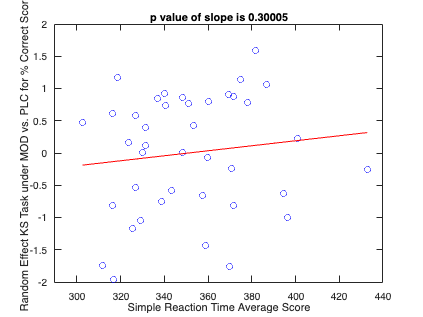

hold on;
plot(xbar,xbar.*BB(2)+BB(1),'-r');
axis([290 440 -2 2]);
xlabel('Simple Reaction Time Average Score')
ylabel('Random Effect KS Task under MOD vs. PLC for % Correct Score')
se = BBint(2,2) - BB(2);
pval = 1-normcdf(BB(2)./se);
tkst = ['p value of slope is ', num2str(pval)];
title(tkst)
hold off;

Load cantab Stockings Task data and merge with knapsack data 

Yall=readtable('PECO_CANTAB_PB_StockCam.csv');

ZallSST=outerjoin(Xall,Yall,'LeftKeys',[2 3],'RightKeys',[2,3]);
writetable(ZallSST,'ZallStockCam.csv')

MANUALLY REORDER so participant 3 is first in ZallStockCam!! Then reload. This way PLC is baseline (participants 3 started with PLC; If you do not reorder, then the assignment of columns of B() below to treatments has to be altered!)

% REORDER so participant 3 is first
Zall=readtable('ZallStockCam.csv');

Correlate average Cantab score with DIFFERENCE in individual deviations from average treatment effect (random effects) between treatment = MOD and treatment = PLC (used to generate Fig S9).


% 1. First compute scores on Cantab per participants (categorical)
% Pick all rows - unless drug effect is needed, in which case, use:
% Pick treatment: MOD=treat 2, DEX=treat 1, MPH=treat 3, PLC=treat 0
% choose_treat = 0;
% rows=Zall.treatment==choose_treat;
rows = (Zall.Drug_Xall==1)|(Zall.Drug_Xall==0); 
xbar = grpstats(Zall.SOCPSMMT(rows),Zall.participant(rows),{'mean'});

% 2. Second generate effects of treatments on performance (or any other regressand)
modelspec = 'attempt_correct ~ sahni_k + Complexity + treatment_cat + (1 + treatment_cat|participant_id)';
mdl = fitglme(Zall,modelspec,'Distribution','binomial','Link','logit')

mdl = Generalized linear mixed-effects model fit by PL

Model information:
    Number of observations            2555
    Fixed effects coefficients           6
    Random effects coefficients        160
    Covariance parameters               10
    Distribution                    Binomial
    Link                            Logit 
    FitMethod                       MPL   

Formula:
    attempt_correct ~ 1 + treatment_cat + sahni_k + Complexity + (1 + treatment_cat | participant_id)

Model fit statistics:
    AIC      BIC      LogLikelihood    Deviance
    11435    11528    -5701.4          11403   

Fixed effects coefficients (95% CIs):
    Name                         Estimate      SE           tStat       DF      pValue        Lower        Upper     
    {'(Intercept)'      }            1.6071      0.22628      7.1021    2549    1.5867e-12       1.1634        2.0508
    {'treatment_cat_DEX'}      


% 3. Next pick individual random effects of chosen treatment (individual
% deviations from mean treatment effect)
% Compute DIFFERENCES in individual random effects treatment vs. PLC
% If data were rearranged so participants 3 is first so that PLC is baseline 
% (see first line in this section) 
% then, in matrix B, columns relate to treatments as follows:
% 1=PLC,2=DEX,3=MPH,4=MOD
% [psi,mse,stats]=covarianceParameters(mdl);
choose_treat = 3;
[B,BNames,statsB]=randomEffects(mdl);
IndDev = B(choose_treat:4:end) - B(1:4:end);

% 4. Finally plot relation individual treatment effects for knapsack task and
% score on CANTAB and compute regression slope confidence intervals
plot(xbar,IndDev,'ob')
[BB BBint] = regress(IndDev,[ones(size(xbar)) xbar],0.1587)

BB =     1.3478
   -0.1277


BBint =    -0.4542    3.1497
   -0.2975    0.0422


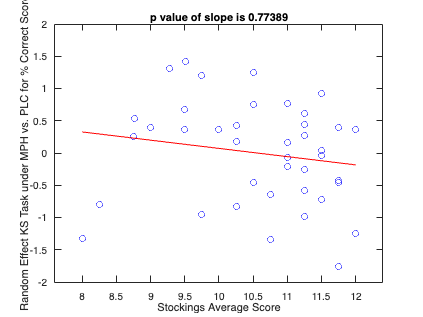

hold on;
plot(xbar,xbar.*BB(2)+BB(1),'-r');
axis([7.6 12.4 -2 2]);
xlabel('Stockings Average Score')
ylabel('Random Effect KS Task under MPH vs. PLC for % Correct Score')
se = BBint(2,2) - BB(2);
pval = 1-normcdf(BB(2)./se);
tkst = ['p value of slope is ', num2str(pval)];
title(tkst)
hold off;

Load cantab Stop Signal Task data and merge with knapsack data 

Yall=readtable('PECO_CANTAB_StopSignal.csv');

ZallSST=outerjoin(Xall,Yall,'LeftKeys',[2 3],'RightKeys',[2,3]);
writetable(ZallSST,'ZallSST.csv')

MANUALLY REORDER so participant 3 is first in ZallSST!! Then reload. This way PLC is baseline (participants 3 started with PLC; If you do not reorder, then the assignment of columns of B() below to treatments has to be altered!)

% REORDER so participant 3 is first
Zall=readtable('ZallSST.csv');

Correlate average Cantab score with DIFFERENCE in individual deviations from average treatment effect (random effects) between treatment = MOD and treatment = PLC (used to generate Fig S9).


% 1. First compute scores on Cantab per participants (categorical)
% Pick all rows - unless drug effect is needed, in which case, use:
% Pick treatment: MOD=treat 2, DEX=treat 1, MPH=treat 3, PLC=treat 0
% choose_treat = 0;
% rows=Zall.treatment==choose_treat;
rows = (Zall.Drug_Xall==1)|(Zall.Drug_Xall==0); 
xbar = grpstats(Zall.SSTSSRT(rows),Zall.participant(rows),{'mean'});

% 2. Second generate effects of treatments on performance (or any other regressand)
modelspec = 'attempt_correct ~ sahni_k + Complexity + treatment_cat + (1 + treatment_cat|participant_id)';
mdl = fitglme(Zall,modelspec,'Distribution','binomial','Link','logit')

mdl = Generalized linear mixed-effects model fit by PL

Model information:
    Number of observations            2555
    Fixed effects coefficients           6
    Random effects coefficients        160
    Covariance parameters               10
    Distribution                    Binomial
    Link                            Logit 
    FitMethod                       MPL   

Formula:
    attempt_correct ~ 1 + treatment_cat + sahni_k + Complexity + (1 + treatment_cat | participant_id)

Model fit statistics:
    AIC      BIC      LogLikelihood    Deviance
    11435    11528    -5701.4          11403   

Fixed effects coefficients (95% CIs):
    Name                         Estimate      SE           tStat       DF      pValue        Lower        Upper     
    {'(Intercept)'      }            1.6071      0.22628      7.1021    2549    1.5867e-12       1.1634        2.0508
    {'treatment_cat_DEX'}      


% 3. Next pick individual random effects of chosen treatment (individual
% deviations from mean treatment effect)
% Compute DIFFERENCES in individual random effects treatment vs. PLC
% If data were rearranged so participants 3 is first so that PLC is baseline 
% (see first line in this section) 
% then, in matrix B, columns relate to treatments as follows:
% 1=PLC,2=DEX,3=MPH,4=MOD
% [psi,mse,stats]=covarianceParameters(mdl);
choose_treat = 2;
[B,BNames,statsB]=randomEffects(mdl);
IndDev = B(choose_treat:4:end) - B(1:4:end);

% 4. Finally plot relation individual treatment effects for knapsack task and
% score on CANTAB and compute regression slope confidence intervals
plot(xbar,IndDev,'ob')
[BB BBint] = regress(IndDev,[ones(size(xbar)) xbar],0.1587)

BB =    -1.4082
    0.0069


BBint =    -2.5842   -0.2323
    0.0012    0.0126


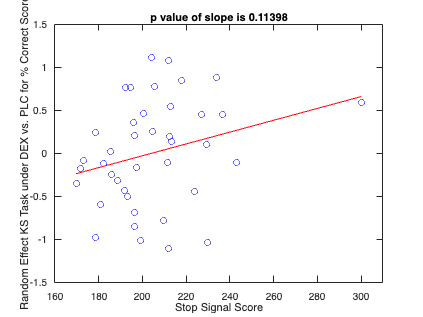

hold on;
plot(xbar,xbar.*BB(2)+BB(1),'-r');
axis([160 310 -1.5 1.5]);
xlabel('Stop Signal Score')
ylabel('Random Effect KS Task under DEX vs. PLC for % Correct Score')
se = BBint(2,2) - BB(2);
pval = 1-normcdf(BB(2)./se);
tkst = ['p value of slope is ', num2str(pval)];
title(tkst)
hold off;